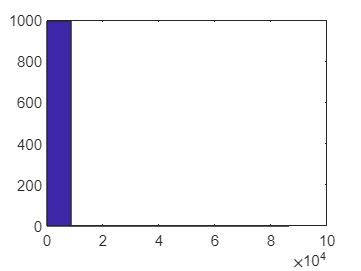

X=lognrnd(2,3,1000,5000);
hist(X(:,7))    

## distribucion empirica

considere X1,X2,...Xn una muestra de una poblacion con distribucion F(t)=P[X<= t]

$\overset{\wedge }{f} \left(t\right)=\frac{\sum_{i=1}^n 1_{\left\lbrace x_i \le t\right\rbrace } }{n}$ es una estimador de F(t)


$$\left\lbrack \begin{array}{ccc}
X & 0 & 1\\
P\left(X=x\right) & 1-p & p
\end{array}\right\rbrack \to E\left(x\right)=p$$


X=-log(rand(10,1));
m=min(X);
M=max(X);
x=m:0.1:M

x =     0.0555    0.1555    0.2555    0.3555    0.4555    0.5555    0.6555    0.7555    0.8555    0.9555    1.0555    1.1555    1.2555    1.3555    1.4555    1.5555    1.6555    1.7555    1.8555    1.9555    2.0555    2.1555    2.2555    2.3555    2.4555    2.5555    2.6555    2.7555    2.8555    2.9555    3.0555    3.1555    3.2555    3.3555    3.4555    3.5555    3.6555    3.7555    3.8555    3.9555


yt=expcdf(x)

yt =     0.0540    0.1440    0.2255    0.2992    0.3659    0.4262    0.4808    0.5302    0.5749    0.6154    0.6520    0.6851    0.7151    0.7422    0.7667    0.7889    0.8090    0.8272    0.8436    0.8585    0.8720    0.8842    0.8952    0.9052    0.9142    0.9223    0.9297    0.9364    0.9425    0.9479    0.9529    0.9574    0.9614    0.9651    0.9684    0.9714    0.9742    0.9766    0.9788    0.9809


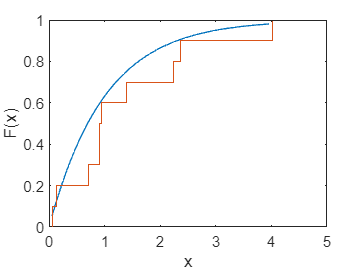

plot(x,yt);
hold on
ecdf(X);
hold off

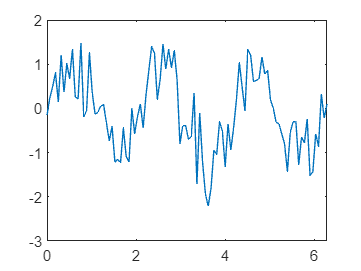

X=linspace(0,2*pi,100);
y=sin(3*X)+0.5*randn(1,100);
plot(X,y)

corr(X',y');

X1=randn(1000,2);
X2=10+randn(800,2);
X=[X1
    X2];
corr(X(:,1),X(:,2))

ans = 0.9623

fitlm(X(:,2),X(:,1))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)    0.16617      0.042887    3.8746    0.00011064
    x1             0.94825     0.0063171    150.11             0


Number of observations: 1800, Error degrees of freedom: 1798
Root Mean Squared Error: 1.37
R-squared: 0.926,  Adjusted R-Squared: 0.926
F-statistic vs. constant model: 2.25e+04, p-value = 0